load 5FoldCV-3-6-9.mat

%Train SVM using a RBF kernel
%Do 5-Fold Cross Validation
gamma=50;
model=fitcsvm(digitNormalize.',class_369.','KernelFunction','rbf','KernelScale',1/sqrt(gamma),'CVPartition',cvp_369);
model.ScoreTransform='logit';

%%ROC and AUC
[predict_label,score]=kfoldPredict(model);
%compute accuracy 
accur=zeros(1,5);
accur(1,1)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[1 2 3 4]);
accur(1,2)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[1 2 3 5]);
accur(1,3)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[1 2 4 5]);
accur(1,4)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[1 3 4 5]);
accur(1,5)=1-kfoldLoss(model,'LossFun','classiferror','Folds',[2 3 4 5]);
disp(accur)

    0.9886    0.9892    0.9903    0.9875    0.9889





figure(1)
confusionchart(class_369.',predict_label);
Title = sprintf('Confusion Matrix of SVM with RBF kernel (Acc = %.2f%%)',mean(accur)*100);
sgtitle(Title);
xlabel('Prediction');ylabel('Ground Truth')

figure(2)
[FPR_rbf,TPR_rbf,T,AUC]=perfcurve(class_369.',predict_label,1);
disp(AUC);

    0.9883



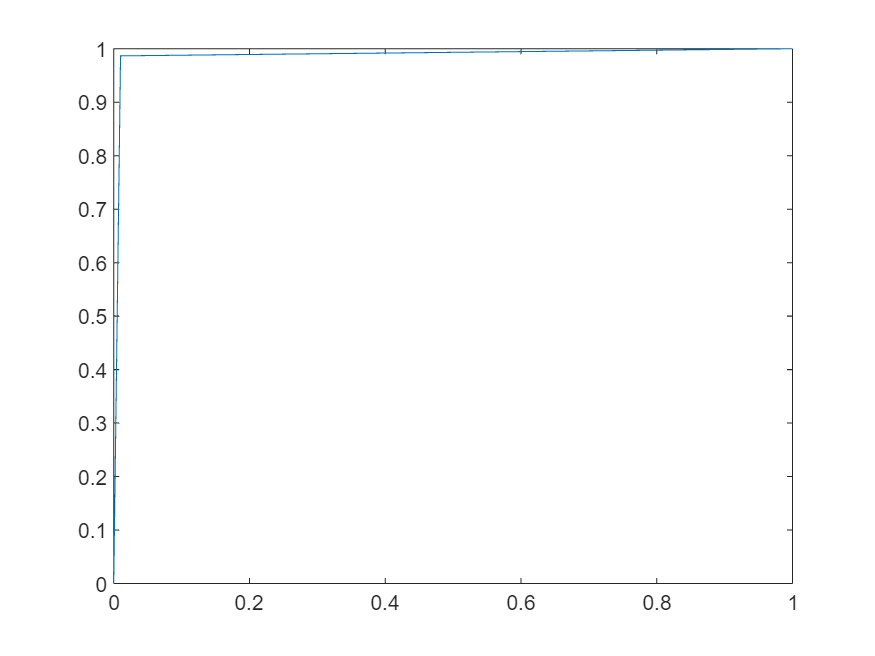

plot(FPR_rbf,TPR_rbf)

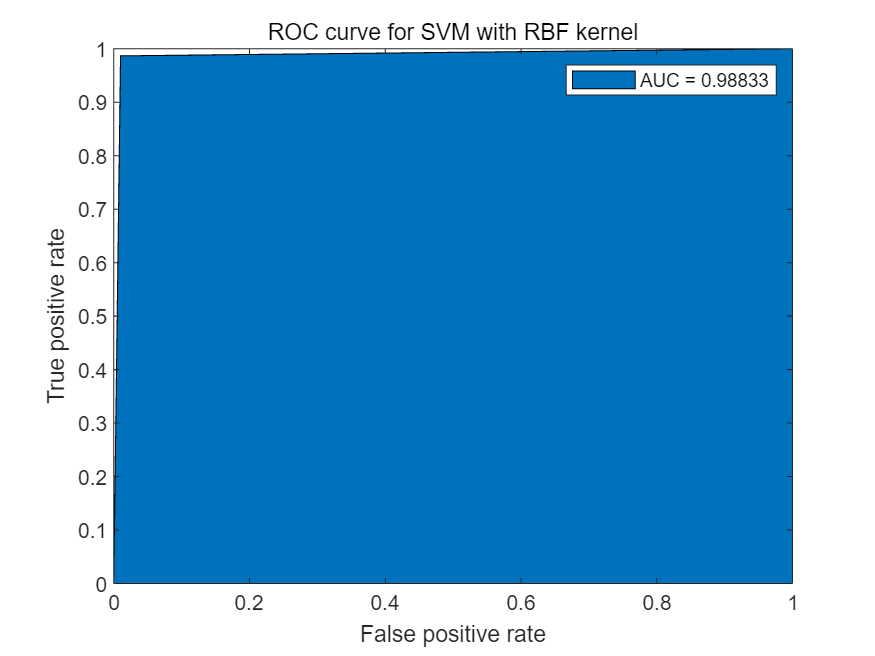

area(FPR_rbf, TPR_rbf);
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve for SVM with RBF kernel')
legend(['AUC = ', num2str(AUC)]);
box on

save svm_rbf_result